Collision avoidance with two Lines

- Step Fill flt. outside the relevant area

- Step do the calculation for RLE "RunLenthPlot.mlx" and Quaddtree "testCollision.mlx"

- Do the targets with "basicPath.mlx"

 you get the Hederf iles "collisiondata_rle_f.h", "collisiondata.h", "mainTaragets.h"

[Li, Lj]= runLenghtEncoding(flt',0.2);
Lj=Li;
n= size(Li)

n =    901     8


Lj(Li==0)=n(1);
d=0.2*pi/180;
xData= theta2*180/pi;
yData=  (theta1(1)+d*(Lj(:,[1,2])))*180/pi;
hold on
title('RunLength Encoded Plot')
xlabel('theta2 [°]')
ylabel('theta1 [°]')
plot(xData, yData);
xData

xData =  -145.0000 -144.8000 -144.6000 -144.4000 -144.2000 -144.0000 -143.8000 -143.6000 -143.4000 -143.2000 -143.0000 -142.8000 -142.6000 -142.4000 -142.2000 -142.0000 -141.8000 -141.6000 -141.4000 -141.2000 -141.0000 -140.8000 -140.6000 -140.4000 -140.2000 -140.0000 -139.8000 -139.6000 -139.4000 -139.2000 -139.0000 -138.8000 -138.6000 -138.4000 -138.2000 -138.0000 -137.8000 -137.6000 -137.4000 -137.2000 -137.0000 -136.8000 -136.6000 -136.4000 -136.2000 -136.0000 -135.8000 -135.6000 -135.4000 -135.2000


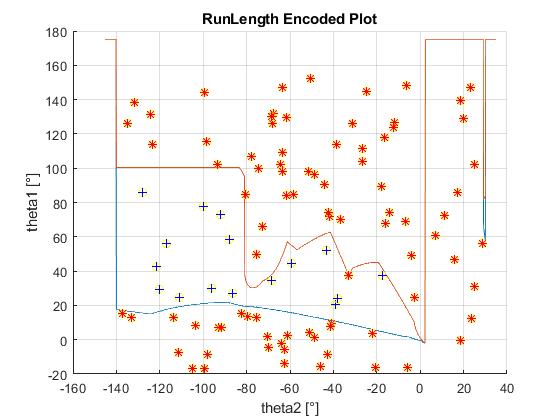

grid on
%hold off

for k=0:100
    w1= (rand(1)-0.1)*3;
    w2= (rand(1)-0.8)*3;
 plot(w2*180/pi,w1*180/pi,'yo');
 kol=checkColl(w1,w2,theta2,yData,d);
 if kol
   plot(w2*180/pi,w1*180/pi,'r*');
 else
   plot(w2*180/pi,w1*180/pi,'b+');
 end
 drawnow
end
hold off


fileID = fopen('collisiondata_rle_1.h','w');
fprintf(fileID,'/*   Data set for Collision with runLength encoding for Darc 1000\n   Author: Klaus-Dieter Rupp */\n');
fprintf(fileID,'#ifndef motionCollisionDataRLE_h\n#define motionCollisionDataRLE_h\n');
fprintf(fileID,'#define MAXLEN_RLE %d\n', length(theta2));
fprintf(fileID,'#define DELTA_RLE %f\n', d);
fprintf(fileID,'short data_rle[][2] ={\n');
for k=1:length(xData)-1
    fprintf(fileID,'{%d, %d},\n',Li(k,1),Li(k,2)); 
end
k=length(xData);
    fprintf(fileID,'{%d, %d}\n',Li(k,1),Li(k,2)); 
fprintf(fileID,'};\n#endif\n');
fclose (fileID);

fileID = fopen('collisiondata_rle_1_f.h','w');
fprintf(fileID,'/*   Data set for Collision with runLength encoding for Darc 1000\n   Author: Klaus-Dieter Rupp */\n');
fprintf(fileID,'#ifndef motionCollisionDataRLEf_h\n#define motionCollisionDataRLEf_h\n');
fprintf(fileID,'#define MAXLEN_RLE %d\n', length(theta2));
fprintf(fileID,'#define DELTA_RLE %f\n', d);
fprintf(fileID,'float data_rle[][3] ={\n');
for k=1:length(xData)-1
    fprintf(fileID,'{%f, %f, %f},\n',xData(k),yData(k,1),yData(k,2)); 
end
k=length(xData);
    fprintf(fileID,'{%f, %f, %f}\n',xData(k),yData(k,1),yData(k,2)); 

fprintf(fileID,'}\n#endif\n');

fclose (fileID);

function kol= checkColl(w1,w2, theta,y, d)
    index=  int16((w2-theta(1))/d+1);
    if index<1 || index > length(theta)
        kol=2;
    else
        delta= w1-y(index,:)*pi/180 ;
        if(delta(1) > 0  && delta(2) < 0)
            kol=0;
        else
            kol=1;
        end
    end
end